# Modeling Flight

## 1. Import and create data

clear all; load('../1-Cleaning/data/dc_corr.mat'); addpath('./functions/');

Convert the volumetric speed to a surface speed (`denss`)

for i_d=1:numel(dc)

    % Combine Speed and angle as complex number
    dc(i_d).u = dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0° is north and 90° is west. -> u is east (+) - west (-) 
    dc(i_d).v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-) 

    % Aggregation according to elevation but weighted by the number of bird.
    % compute height bin size
    tmp=diff(double([0 max(0, (1:dc(i_d).levels).*dc(i_d).interval - dc(i_d).height )]))/1000;
    dc(i_d).denss = dc(i_d).dens*tmp';
    % Compute number of bird
    nb_bird=dc(i_d).dens .* repmat(tmp,size(dc(i_d).dens,1),1);
    % need to account only when speed and direction data are present
    nb_bird_2 = nb_bird;
    nb_bird_2(isnan(dc(i_d).ff) | isnan(dc(i_d).dd))=nan;
    % remove speed above 25.
    % nb_bird_2(dc(i_d).ff>25)=nan;
    % check that at direction is representatife of at least 50% of the bird
    nb_bird_2(nansum(nb_bird_2,2)./nansum(nb_bird,2)<.5,:)=nan;
    % check that at direction is representatife of at least 3 altitude bins
    nb_bird_2(sum(nb_bird_2>0,2)<4,:)=nan;

    w_MTR = nb_bird_2 ./ repmat(nansum(nb_bird_2,2),1,size(nb_bird_2,2));
    
    dc(i_d).vs = nansum(w_MTR.* dc(i_d).v,2);
    dc(i_d).us = nansum(w_MTR.* dc(i_d).u,2);
    dc(i_d).NNT = datenum(dc(i_d).time'-mean([dc(i_d).sunrise;dc(i_d).sunset])) ./ datenum(dc(i_d).sunrise-dc(i_d).sunset)*2;
end

uniqueDate = round(datenum(datetime(start_date:end_date)))';
dclat = [dc.lat]';
dclon = [dc.lon]';

Create the data structure `data`

dens_lim = 0.002;
data=[];
t15min = bsxfun(@plus,datenum(start_date:1/24/60*15:end_date),(-4:4)'*1/24/60);
t15min = datetime(sort(t15min(:)),'ConvertFrom','datenum');

for i_d=1:numel(dc)
    id = dc(i_d).NNT(:)>=-1 & dc(i_d).NNT(:)<=1 & dc(i_d).denss>dens_lim & (dc(i_d).vs~=0 | dc(i_d).us~=0) & ismember(dc(i_d).time,t15min);
    d=table();
    d.v=dc(i_d).vs(id);
    d.u=dc(i_d).us(id);
    d.dens=dc(i_d).denss(id);
    d.NNT = dc(i_d).NNT(id)';
    d.radar=i_d*ones(sum(id),1);
    d.lat=dc(i_d).lat*ones(sum(id),1);
    d.lon=dc(i_d).lon*ones(sum(id),1);
    d.time = datenum(dc(i_d).time(id));
    [~,d.day]=ismember(round(datenum(dc(i_d).sunrise(id)))',uniqueDate);
    d.dayradar = sub2ind([numel(dc) numel(uniqueDate)],d.radar, d.day);
    data = [data ; d ];
end

clear d dens_lim

## 2. Standardization

Check for non-stationarities as a function of the progression of the night. Not trend used

figure('position',[0 0 1000 400]);  
subplot(2,1,1);plot(data.NNT,data.u,'.k'); ylabel('E-W speed [m/s]');
subplot(2,1,2);plot(data.NNT,data.v,'.k');ylabel('N-S speed [m/s]');
xlabel('Normalized Night Time (NNT) (-1: sunset | 1: sunrise)'); 

Check for spatial non-stationarities. Not trend used.

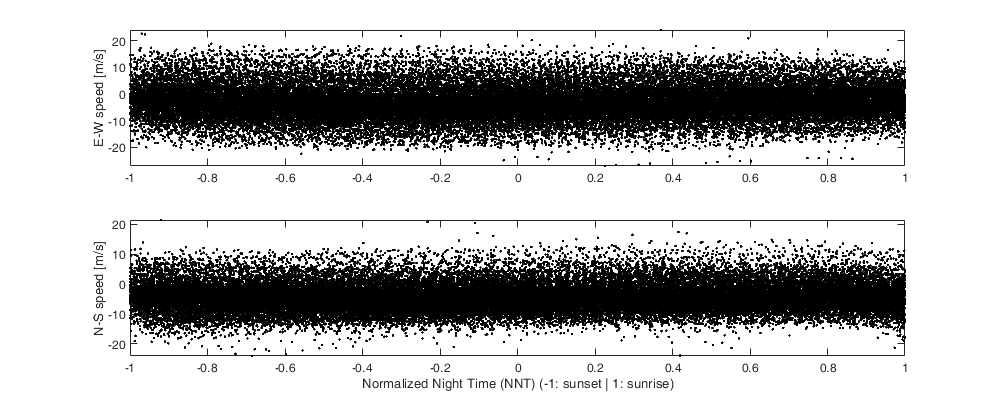

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,splitapply(@mean,data.u,data.radar),'filled','MarkerEdgeColor','k'); 

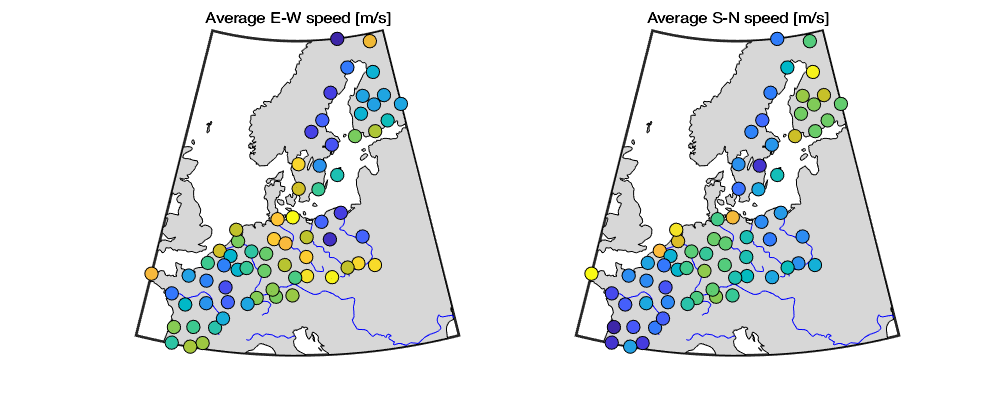

title('Average E-W speed [m/s]'); 
subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,splitapply(@mean,data.v,data.radar),'filled','MarkerEdgeColor','k'); 
title('Average S-N speed [m/s]'); 

Standardize

uv.trans.mean = [mean(data.u) mean(data.v)];
uv.trans.std = [std(data.u) std(data.v)];

uv.ut = ( data.u-uv.trans.mean(1)) / uv.trans.std(1);
uv.vt = ( data.v-uv.trans.mean(2)) / uv.trans.std(2);

Illustration

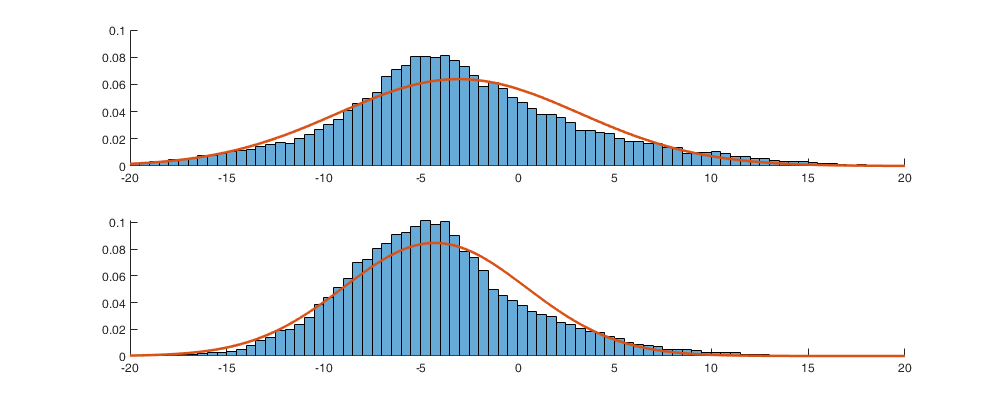

figure('position',[0 0 1000 400]);  
subplot(2,1,1); hold on;
histogram(data.u,'Normalization','pdf')
x=-20:0.1:20;
plot(x,normpdf(x,uv.trans.mean(1),uv.trans.std(1)),'LineWidth',2); xlim([-20 20])
subplot(2,1,2); hold on
histogram(data.v,'Normalization','pdf')
plot(x,normpdf(x,uv.trans.mean(2),uv.trans.std(2)),'LineWidth',2); xlim([-20 20])

## 3. Covariance function

Built the matrix of distances of the data. Distence (or difference) in lattitude, longitude, time and value. 

Ddist_sm=squareform(pdist(repmat([dclat dclon], numel(uniqueDate),1),@lldistkm));

D=table();
for i_t=1:numel(uniqueDate)
    d=table();
    id = find(data.day==i_t);
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    
    A = ones(numel(id));
    B = tril(A);
    D=[D ; d(B(:)==1,:)];
end

### 3.1 Empirical covariance function

uv_cov_d=[0 eps 200 300 400 600 1000 1500];
uv_cov_t=[0 eps .015 .025 .045 .08 .1 .2 .25  .35]; 
[uv_cov_D,uv_cov_T]=meshgrid(uv_cov_d(1:end-1)+diff(uv_cov_d)/2,uv_cov_t(1:end-1)+diff(uv_cov_t)/2);

uv_cov_emp_grid_u=nan(size(uv_cov_D));
uv_cov_emp_grid_v=nan(size(uv_cov_D));
uv_cov_D_emp=nan(size(uv_cov_D));
uv_cov_T_emp=nan(size(uv_cov_T));

nb=nan(size(uv_cov_D));
for i_d=1:numel(uv_cov_d)-1
    id1 = find(D.Ddist>=uv_cov_d(i_d) & D.Ddist<uv_cov_d(i_d+1));
    for i_t=1:numel(uv_cov_t)-1
        id2 = id1(D.Dtime(id1)>=uv_cov_t(i_t) & D.Dtime(id1)<uv_cov_t(i_t+1));
        uv_cov_emp_grid_u(i_t,i_d)=mean(uv.ut(D.Did1(id2)) .* uv.ut(D.Did2(id2)));
        uv_cov_emp_grid_v(i_t,i_d)=mean(uv.vt(D.Did1(id2)) .* uv.vt(D.Did2(id2)));
        uv_cov_D_emp(i_t,i_d) = nanmean(D.Ddist(id2)); 
        uv_cov_T_emp(i_t,i_d) = nanmean(D.Dtime(id2));
        nb(i_t,i_d)=numel(id2);
    end
end

% figure('position',[0 0 1000 400]);  
% subplot(1,2,1); surf(uv_cov_D_emp,uv_cov_T,uv_cov_emp_grid_u);  xlabel('Distance [km]'); ylabel('Time [Days]');
% subplot(1,2,2); surf(uv_cov_D_emp,uv_cov_T,uv_cov_emp_grid_v);  xlabel('Distance [km]'); ylabel('Time [Days]');
%subplot(1,3,3); surf(uv_cov_D,uv_cov_T,nb);  xlabel('Distance [km]'); ylabel('Time [Days]');

### 3.2 Calibrate the covariance function 

Gneiting = @(dist,time,range_dist,range_time,delta,gamma,beta) 1./( (time./range_time).^(2.*delta) +1 ) .* exp(-(dist./range_dist).^(2.*gamma) );
Gneiting_fit = @(parm) parm(1)*(uv_cov_D_emp==0 & uv_cov_T_emp==0) + parm(2).*Gneiting(uv_cov_D_emp,uv_cov_T_emp,parm(3),parm(4),parm(5),parm(6),parm(7));

parm0 =[.1 .9 300 5 .5 .5 .5];
parm_min=[0 0 0.0001 0 0 0 0 ]';
parm_max=[nancov(uv.ut) nancov(uv.ut) 3000 10 1 1 1]';

rmse_u = @(parm) sum(sum( 1000*abs(uv_cov_emp_grid_u).* ( Gneiting_fit(parm) -  uv_cov_emp_grid_u ).^2 ));
uv.cov.parm_u = fmincon(rmse_u,parm0,[],[],[1 1 0 0 0 0 0],nancov(uv.vt),parm_min,parm_max,[]); % ,optimset('PlotFcn',@optimplotfval)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uv.cov.Cu = @(D,T) uv.cov.parm_u(1)*(D==0 & T==0) + uv.cov.parm_u(2).*Gneiting(D,T,uv.cov.parm_u(3),uv.cov.parm_u(4),uv.cov.parm_u(5),uv.cov.parm_u(6),uv.cov.parm_u(7));
fprintf(['nugget\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],uv.cov.parm_u)

nugget	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.065	 0.935	 1048.898		 0.997			 0.722			 0.457			 0.500


parm_max=[nancov(uv.vt) nancov(uv.vt) 3000 10 1 1 1]';
rmse_u = @(parm) sum(sum( 1000*abs(uv_cov_emp_grid_v).*( Gneiting_fit(parm) -  uv_cov_emp_grid_v ).^2 ));
uv.cov.parm_v = fmincon(rmse_u,parm0,[],[],[1 1 0 0 0 0 0],nancov(uv.vt),parm_min,parm_max,[]); % ,optimset('PlotFcn',@optimplotfval)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


uv.cov.Cv = @(D,T) uv.cov.parm_v(1)*(D==0 & T==0) + uv.cov.parm_v(2).*Gneiting(D,T,uv.cov.parm_v(3),uv.cov.parm_v(4),uv.cov.parm_v(5),uv.cov.parm_v(6),uv.cov.parm_v(7));
fprintf(['nugget\t var\t range distance[km]\t range time[day]\t shape distance (delta)\t shape time (gamma)\t separability (beta)\n%.3f\t %.3f\t %.3f\t\t %.3f\t\t\t %.3f\t\t\t %.3f\t\t\t %.3f'],uv.cov.parm_v)

nugget	 var	 range distance[km]	 range time[day]	 shape distance (delta)	 shape time (gamma)	 separability (beta)
0.087	 0.913	 559.772		 0.911			 0.542			 0.520			 0.500

Figure Ilustration

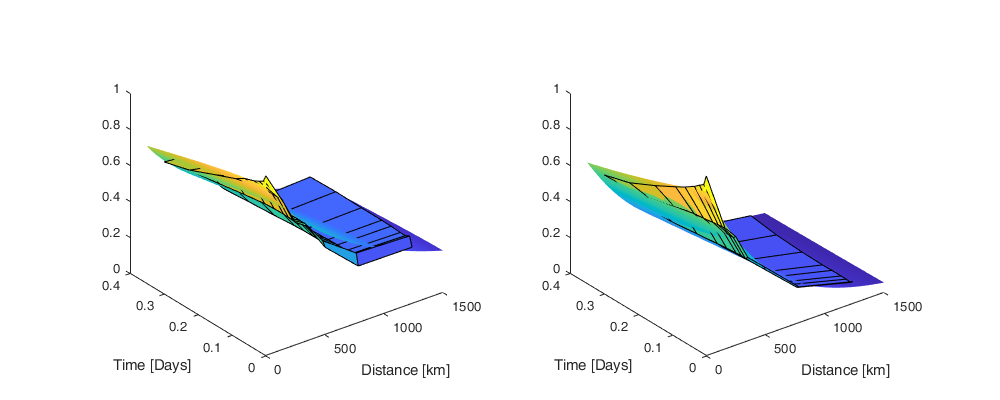

[tmpD,tmpT] = meshgrid(uv_cov_d(1):1:uv_cov_d(end),uv_cov_t(1):0.01:uv_cov_t(end));

figure('position',[0 0 1000 400]);
subplot(1,2,1); hold on;
s=surf(tmpD,tmpT,uv.cov.Cu(tmpD,tmpT));
surf(uv_cov_D_emp,uv_cov_T,uv_cov_emp_grid_u);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

subplot(1,2,2); hold on;
s=surf(tmpD,tmpT,uv.cov.Cv(tmpD,tmpT));
surf(uv_cov_D_emp,uv_cov_T,uv_cov_emp_grid_v);  xlabel('Distance [km]'); ylabel('Time [Days]');
s.EdgeColor='none'; view(3)

## 4. Save

Save the parameters of the model. 

save('data/Flight_inference.mat','uv','data','-v7.3')
% writetable(data,'data/Density_data.csv')